**Communication scheme with the IRS-assisted link and transmission 802.11ad**

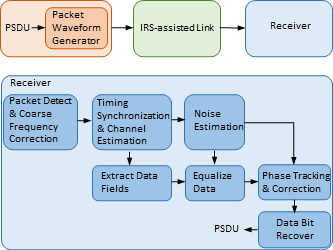

**Parameters**

Parameters
pos_ue = p_focus;%the MU's position is centered at the IRS focus

**IRS configuration**

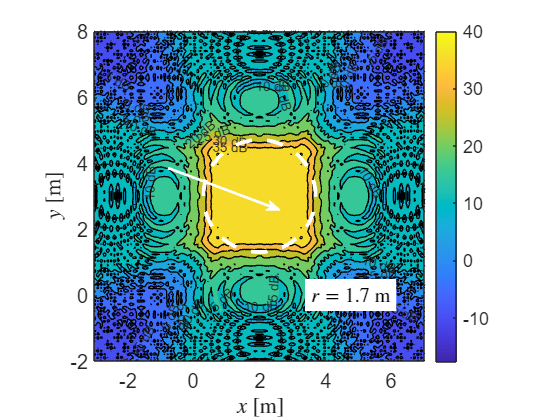

IRS_config

#### 802.11ad transmissions

addpath('./802_11ad_functions')

PER=zeros(total_pos_points,total_pos_points);
numPacketErrors = 0;%counter for the total of errors
SNR_radius_ang=zeros(total_pos_points,total_pos_points);
pathloss=zeros(total_pos_points,total_pos_points);
distance_AP_IRS_MU=zeros(1,total_pos_points);

ind = wlanFieldIndices(cfgDMG);

numPkt = 1; % Index of the transmitted packet

tic;
for i_radius=1:total_pos_points%loop in the radial dimension
    i_radius/total_pos_points*100
    for i_ang=1:total_pos_points %loop in the angular dimension

        %The MU moves in circles paralel to the yz-plane and
        %centered at p_focus. 
        pos_ue(2)=r_MU(i_radius)*cos(angle_MU(i_ang))+p_focus(2);
        pos_ue(3)=r_MU(i_radius)*sin(angle_MU(i_ang))+p_focus(3);
        pos_ue_idy=floor((pos_ue(2)-p_focus(2))/Dobs*N)+floor(N/2)+1;
        pos_ue_idz=floor((pos_ue(3)-p_focus(3))/Dobs*N)+floor(N/2)+1;
        
        for f=1:numPackets %loop in the total of packets per position
            %802.11n waveform generation
%             % Set random substream index per iteration to ensure that each
%             % iteration uses a repeatable set of random numbers
%             stream = RandStream('combRecursive','Seed',1);
%             stream.Substream = isnr;
%             RandStream.setGlobalStream(stream);
            %PDSU: random generation of Bytes
            % Generate a packet waveform
            psdu = randi([0 1],cfgDMG.PSDULength*8,1);      
            txWaveform = wlanWaveformGenerator(psdu,cfgDMG);
            % Add delay and trailing zeros accounting for channel
            % impairments
            tx = [zeros(delay,1); txWaveform; zeros(zeroPadding,1)];
                    
            %channel noise
            pathloss(i_radius,i_ang)=Path_loss(pos_ue_idy,pos_ue_idz);
            awgnChannel = comm.AWGNChannel('NoiseMethod','Variance',...
                'Variance',db2pow(NoiseFloor-30));
            %MU output: channel plus MU's thermal noise
            MU_out = awgnChannel(tx*sqrt(pathloss(i_radius,i_ang)));
            % Add CFO
            %MU_out = frequencyOffset(MU_out,fs,freqOffset);

            % Packet detection
            threshold = 0.03; % Good for low SNRs
            pktStartOffset = dmgPacketDetect(MU_out,0,threshold);
            if isempty(pktStartOffset) % If empty no STF detected; packet error
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end
            
            % Symbol timing and channel estimate
            preamblefield = MU_out(pktStartOffset+1:pktStartOffset+ind.DMGHeader(2),:);
            [symbolTimingOffset,chanEst] = dmgTimingAndChannelEstimate(preamblefield);
            startOffset = pktStartOffset+symbolTimingOffset;
            
            % If not enough samples to decode detected data field start,
            % then assume synchronization error and packet error
            if (startOffset+ind.DMGData(2))>size(MU_out,1)
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end

            % Noise estimation using the STF as repeating sequence
            stf = MU_out(pktStartOffset+(ind.DMGSTF(1):ind.DMGSTF(2)));
            nVarEst = dmgSTFNoiseEstimate(stf);

            % Extract data field (ignore first GI)
            rxData = MU_out(startOffset+((ind.DMGData(1)+Ngi):ind.DMGData(2)));

            % Linear frequency domain equalization
            rxEqDataBlks = dmgSingleCarrierFDE(rxData,chanEst,nVarEst);

            % Unique word phase tracking
            rxEqDataBlks = dmgUniqueWordPhaseTracking(rxEqDataBlks);

            % Discard GI from all blocks
            rxDataSym = rxEqDataBlks(1:end-Ngi,:); 

            % Recover the transmitted PSDU from DMG Data field
            dataDecode = wlanDMGDataBitRecover(rxDataSym,nVarEst,cfgDMG);

            % Determine if any bits are in error, i.e. a packet error
            packetError = any(biterr(psdu,dataDecode));
            numPacketErrors = numPacketErrors+packetError;
            numPkt = numPkt+1;
            
            SNR_radius_ang(i_radius,i_ang)=SNR(pos_ue_idy,pos_ue_idz);
            PER(i_radius,i_ang)=numPacketErrors/numPackets;
            numPacketErrors=0;
        end

ans = 20

ans = 40

ans = 60

ans = 80

ans = 100

Index in position 1 is invalid. Array indices must be positive integers or logical values.

    end
end
toc;

%evaluating throughput in Mbps
numPacketErrors=sum(PER,2);
fs = wlanSampleRate(cfgDMG);%sampling frequency
txtime = (length(txWaveform)/fs)*1e6-idleTime; % Packet duration
throughput=1e-6*((numPackets-numPacketErrors)*(8*cfgDMG.PSDULength)/(numPackets*(txtime+idleTime)*1e-6));